% a04_p1_pr_debugging_v3

% p1: part 1
% v3: include 6 models

% This script sets ExpInfo.nTrials = 1e4 and counts = 1 to debug, i.e., test if
% fitted parameters are the same as true parameters. Also plots true
% parameters against real parameters
 
clear all; close all; clc; rng(1); %parpool(20);

%% initiate confusion matrix

nModel = 6;
CM = zeros(nModel);
counts = 1;

%% experimental parameters

ExpInfo.ifi              = 1000/60;
ExpInfo.SOA              = [-0.5000, -0.3000, -0.2500, -0.2000, -0.1500, -0.1000,...
    -0.0500, 0, 0.0500, 0.1000, 0.1500, 0.2000, 0.2500, 0.3000, 0.5000]*1000; % in ms
ExpInfo.lenS             = length(ExpInfo.SOA);
ExpInfo.nTrials          = 1e4; % num of trials per SOA

%% ground truth parameters

% used the ground truth parameters from sub7 sess 7 SOA = -300 ms
TruePara                 = {[40, -20, 70, 50, 110, 80, 0.01, 0.06], ...%M1
    [40, -20, 70, 110, 80, 0.01, 0.06], ...%M2
    [40, -20, 70, 50, 110, 0.01, 0.06], ...%M3
    [40, -20, 70, 110, 0.01, 0.06], ...%M4
    [40, 70, 110, 80, 0.01, 0.06], ...%M5
    [40, 70, 110, 0.01, 0.06]};%M6

ParaLabel = {{'\mu_{pre}','\mu_{post}','\sigma_{pre}','\sigma_{post}','criterion_{pre}','criterion_{post}','\lambda_{pre}','\lambda_{post}'},...
    {'\mu_{pre}','\mu_{post}','\sigma','criterion_{pre}','criterion_{post}','\lambda_{pre}','\lambda_{post}'},...
    {'\mu_{pre}','\mu_{post}','\sigma_{pre}','\sigma_{post}','criterion','\lambda_{pre}','\lambda_{post}'},...
    {'\mu_{pre}','\mu_{post}','\sigma','criterion','\lambda_{pre}','\lambda_{post}'},...
    {'\mu','\sigma','criterion_{pre}','criterion_{post}','\lambda_{pre}','\lambda_{post}'},...
    {'\mu','\sigma','criterion','\lambda_{pre}','\lambda_{post}'}};

%% functions

% define PMF
P_Afirst                 = @(SOA, mu, sig, c, lambda) lambda/3 + (1-lambda).*normcdf(-c, SOA - mu, sig);
P_Vfirst                 = @(SOA, mu, sig, c, lambda) lambda/3 + (1-lambda).*(1 - normcdf(c, SOA-mu, sig));
P_simultaneous           = @(SOA, mu, sig, c, lambda) ...
    1 - (lambda/3 + (1-lambda).*normcdf(-c, SOA - mu, sig)) ...
    - (lambda/3 + (1-lambda).*(1 - normcdf(c, SOA-mu, sig)));

M1 = {
    @(p) P_Vfirst(ExpInfo.SOA, p(1), p(3), p(5), p(7));...
    @(p) P_simultaneous(ExpInfo.SOA, p(1), p(3), p(5), p(7));...
    @(p) P_Afirst(ExpInfo.SOA, p(1), p(3), p(5), p(7));...
    @(p) P_Vfirst(ExpInfo.SOA, p(2), p(4), p(6), p(8));...
    @(p) P_simultaneous(ExpInfo.SOA, p(2), p(4), p(6), p(8));
    @(p) P_Afirst(ExpInfo.SOA, p(2), p(4), p(6), p(8))};

M2 = {
    @(p) P_Vfirst(ExpInfo.SOA, p(1), p(3), p(4), p(6));...
    @(p) P_simultaneous(ExpInfo.SOA, p(1), p(3), p(4), p(6));...
    @(p) P_Afirst(ExpInfo.SOA, p(1), p(3), p(4), p(6));...
    @(p) P_Vfirst(ExpInfo.SOA, p(2), p(3), p(5), p(7));...
    @(p) P_simultaneous(ExpInfo.SOA, p(2), p(3), p(5), p(7));...
    @(p) P_Afirst(ExpInfo.SOA, p(2), p(3), p(5), p(7))};

M3 = {
    @(p) P_Vfirst(ExpInfo.SOA, p(1), p(3), p(5), p(6));...
    @(p) P_simultaneous(ExpInfo.SOA, p(1), p(3), p(5), p(6));...
    @(p) P_Afirst(ExpInfo.SOA, p(1), p(3), p(5), p(6));...
    @(p) P_Vfirst(ExpInfo.SOA, p(2), p(4), p(5), p(7));...
    @(p) P_simultaneous(ExpInfo.SOA, p(2), p(4), p(5), p(7));...
    @(p) P_Afirst(ExpInfo.SOA, p(2), p(4), p(5), p(7))};

M4 = {
    @(p) P_Vfirst(ExpInfo.SOA, p(1), p(3), p(4), p(5));...
    @(p) P_simultaneous(ExpInfo.SOA, p(1), p(3), p(4), p(5));...
    @(p) P_Afirst(ExpInfo.SOA, p(1), p(3), p(4), p(5));...
    @(p) P_Vfirst(ExpInfo.SOA, p(2), p(3), p(4), p(6));...
    @(p) P_simultaneous(ExpInfo.SOA, p(2), p(3), p(4), p(6));...
    @(p) P_Afirst(ExpInfo.SOA, p(2), p(3), p(4), p(6))};

M5 = {
    @(p) P_Vfirst(ExpInfo.SOA, p(1), p(2), p(3), p(5));...
    @(p) P_simultaneous(ExpInfo.SOA, p(1), p(2), p(3), p(5));...
    @(p) P_Afirst(ExpInfo.SOA, p(1), p(2), p(3), p(5));...
    @(p) P_Vfirst(ExpInfo.SOA, p(1), p(2), p(4), p(6));...
    @(p) P_simultaneous(ExpInfo.SOA, p(1), p(2), p(4), p(6));...
    @(p) P_Afirst(ExpInfo.SOA, p(1), p(2), p(4), p(6))};

M6 = {
    @(p) P_Vfirst(ExpInfo.SOA, p(1), p(2), p(3), p(4));...
    @(p) P_simultaneous(ExpInfo.SOA, p(1), p(2), p(3), p(4));...
    @(p) P_Afirst(ExpInfo.SOA, p(1), p(2), p(3), p(4));...
    @(p) P_Vfirst(ExpInfo.SOA, p(1), p(2), p(3), p(5));...
    @(p) P_simultaneous(ExpInfo.SOA, p(1), p(2), p(3), p(5));...
    @(p) P_Afirst(ExpInfo.SOA, p(1), p(2), p(3), p(5))};

models = {M1; M2; M3; M4; M5; M6};


%% run model fitting for multiple times

% initialization
[deltaAIC, estP] = deal(cell(counts, nModel));

for count = 1:counts
    count

    %% simulate fake datasets for 6 models
    for iModel                   = 1:nModel

        % for the specific model and its corresponding ground-truth
        % parameter sets, generate the probability of reporting: Vfirst,
        % simultaneous, Afirst in pretest; Vfirst, simultaneous, Afirst in
        % posttest
        p_all_cond               = NaN(6, ExpInfo.lenS); % len of conditions x len of SOA levels
        Para                     = TruePara{iModel}; % true parameters for this model
        for iCondition           = 1:6
            p_all_cond(iCondition,:) = models{iModel}{iCondition}(Para);
        end

        % simulate data set
        sim_r_org                = cell(1,2);
        for s                    = 1:2 % loop through pre and post session
            p                        = p_all_cond(((s-1)*3+1):s*3, :); % pre and post probability of reporting V,simul, A
            sim_r_org{s}             = sampleMatrix(p, ExpInfo.nTrials);
        end

        %% fit fake data to 6 models 

        % obtain best-fitting parameters and AIC for each model
        [deltaAIC{count, iModel}, estP{count, iModel}]  = para_comp_fitting_fake_data_v3(sim_r_org, ExpInfo, iModel);

        % iBest is the index of model that best fits this specific fake data set
        [M iBEST] = min(deltaAIC{count, iModel});
        BEST = deltaAIC{count, iModel} == M;
        BEST = BEST / sum(BEST);
        CM(iModel,:) = CM(iModel,:) + BEST;

    end
end

count = 1

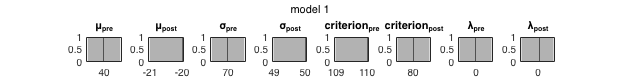

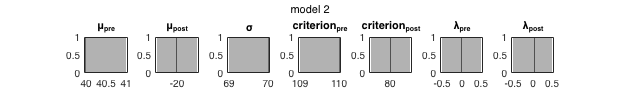

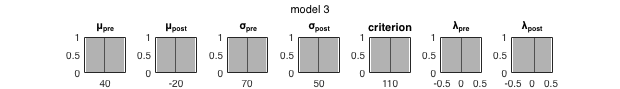

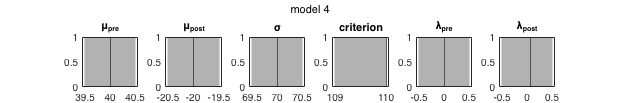

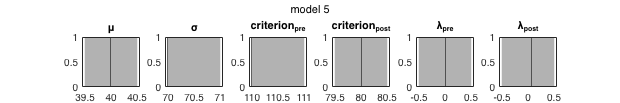

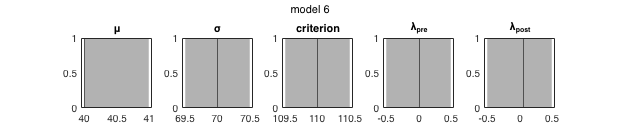

%% summary plot of true and fitted parameters

for m            = 1:nModel % for each model
    true_para = TruePara {m};
    n_para = length(true_para);
    fit_para = NaN(size(true_para));
    for c = 1:counts
        fit_para(c,:) = cell2mat(estP{c,m}); %c: trial of fits; first m: generating model; second m: fitted model
    end
    figure; clf; hold on % create a figure for each model
    set(gcf, 'Position', [0,0,200*n_para,200])
    sgtitle(['model ' num2str(m)])
    for p = 1:n_para % create subplot for each parameter
        subplot(1,n_para,p)
        histogram(fit_para(:,p),'EdgeAlpha',0,'FaceColor','k','FaceAlpha',0.3);
        xline(true_para(p))
        title(ParaLabel{m}{p})
    end
end